## P1)


$$\begin{array}{l}
G_1 \left(s\right)=\frac{1}{s};G_2 \left(s\right)=\frac{1}{\;\frac{J}{c}s^2 +\frac{r}{c}s+1};G_3 \left(s\right)=\frac{1}{c}\\
\frac{J}{c}=0\ldotp 0033s^{2\;} ;\frac{r}{c}=0\ldotp 0125s;c=0\ldotp 7035\frac{\textrm{kg}}{s^2 }\\
G_{\textrm{sys}} \left(s\right)=G_1 \left(s\right)\cdot G_2 \left(s\right)=\frac{1}{s\;\left(\frac{J}{c}s^2 +\frac{r}{c}s+1\right)}=\frac{1}{\frac{J}{c}s^3 +\frac{r}{c}s^2 +s}\\
G_{\textrm{dis}} \left(s\right)=G_3 \left(s\right)\cdot G_2 \left(s\right)=\frac{1}{c\left(\frac{J}{c}s^2 +\frac{r}{c}s+1\right)}=\frac{1}{\left(Js^2 +\textrm{rs}+c\right)}
\end{array}$$


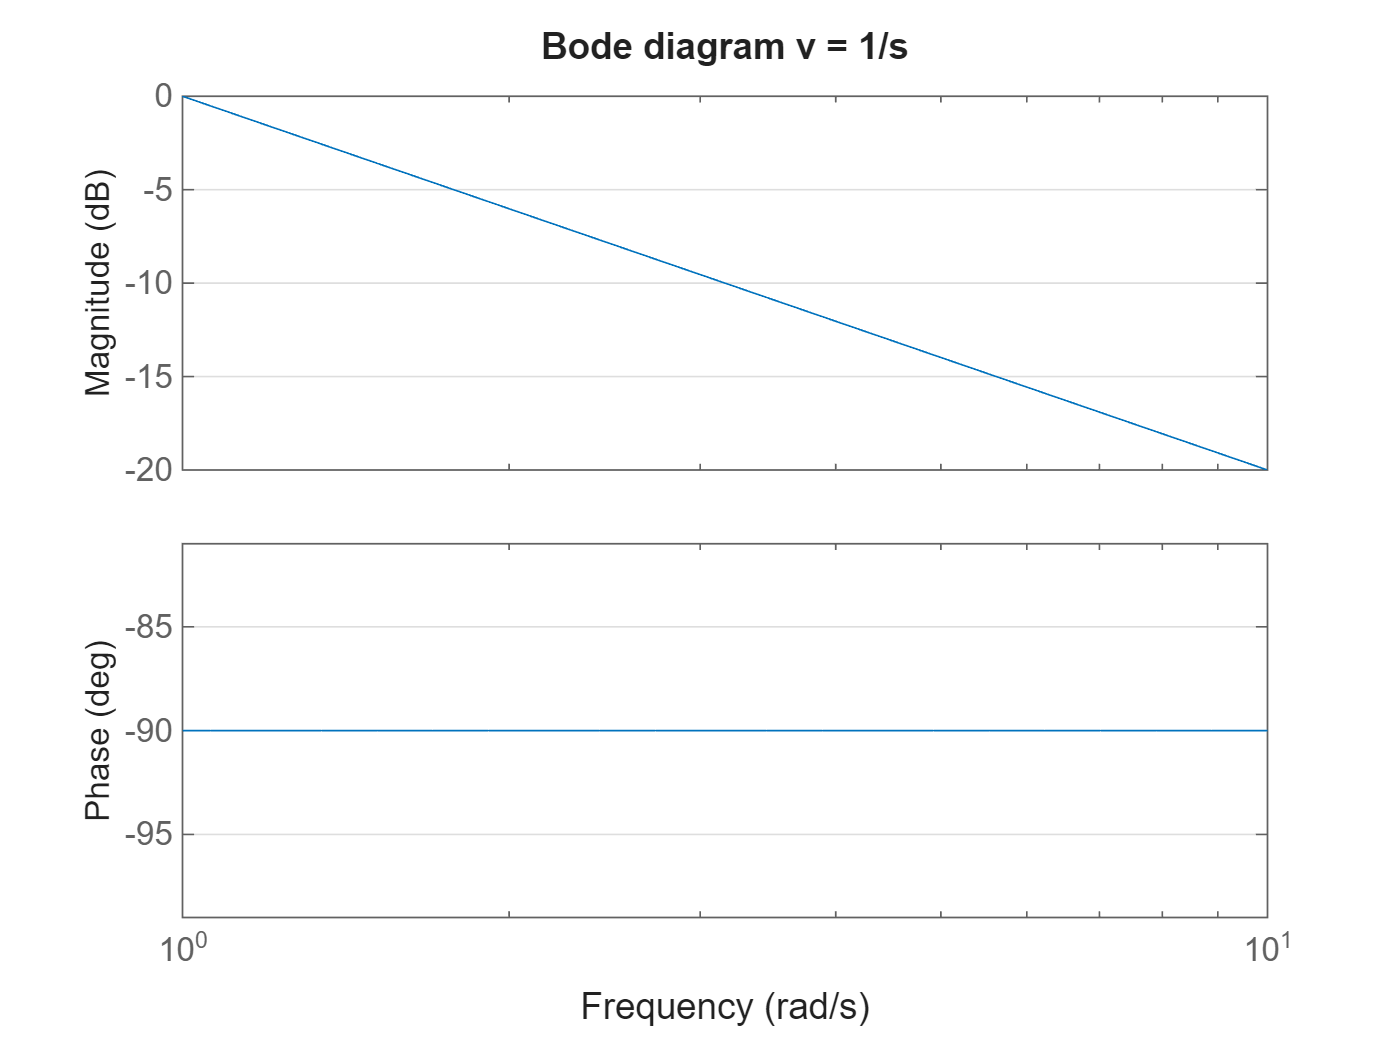

% Parameters
c = 0.7035;
J = 0.0033*c;
r = 0.0125*c;

s = tf('s');

% seperated transfer functions
G1 = 1/s;
G2 = 1 / ((J/c)*s^2 + (r/c)*s + 1);
G3 = 1/c;

% combined transfer functions
G_sys = G1 * G2;
G_dis = G3 * G2;

%% Bodediagramme
figure;
bode(G1);
title('Bode diagram v = 1/s');
grid on;

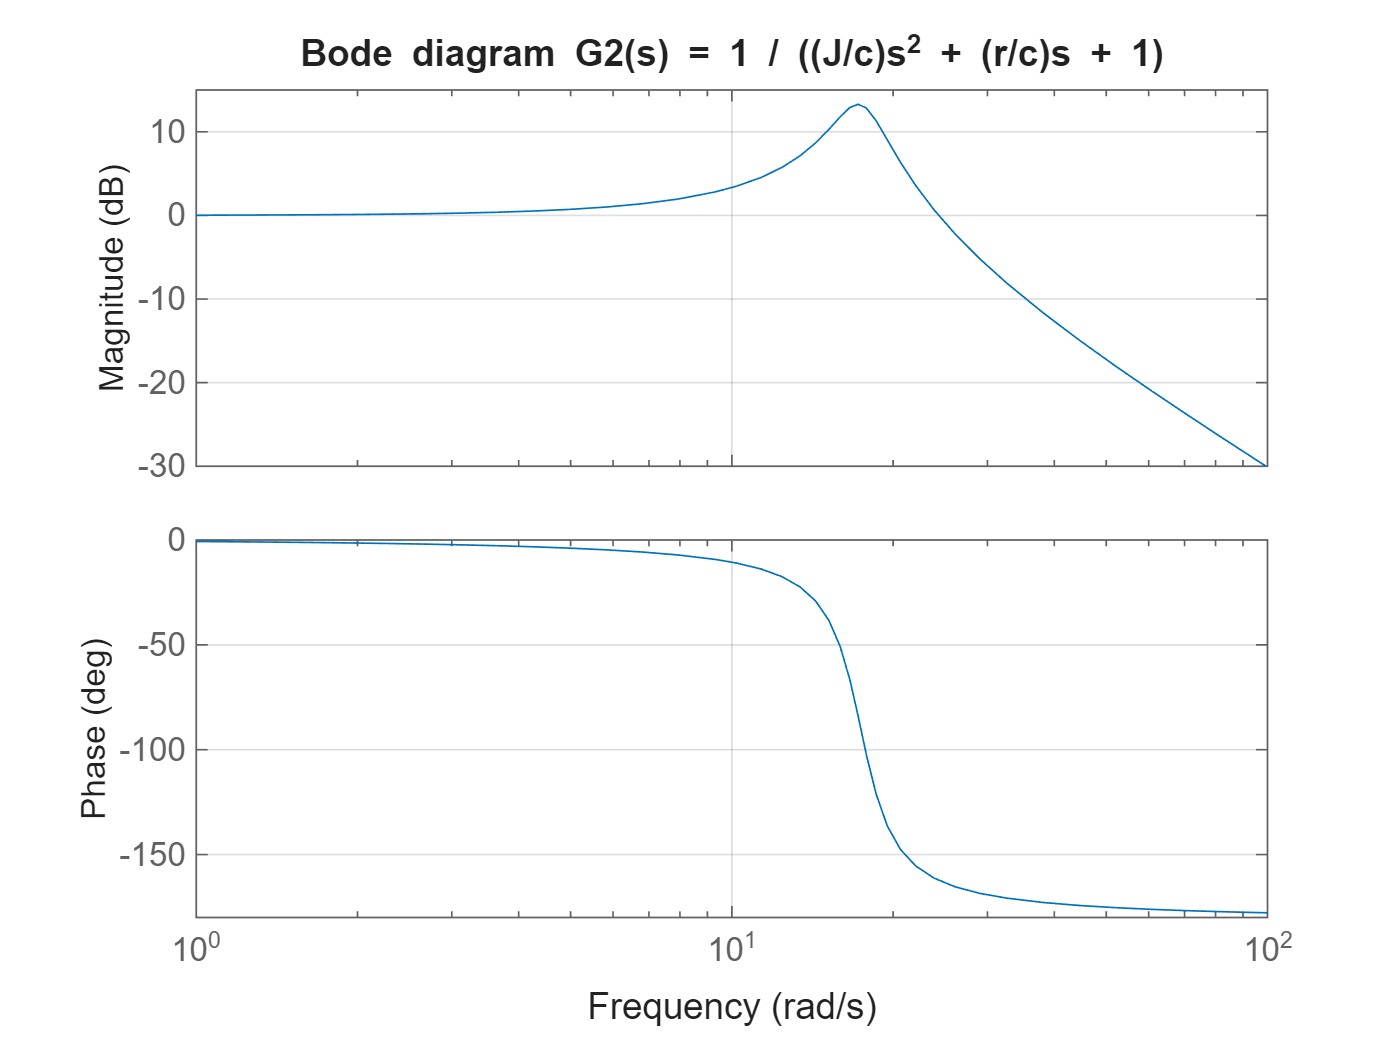


figure;
bode(G2);
title('Bode diagram G{2}(s) = 1 / ((J/c)s^2 + (r/c)s + 1)');
grid on;

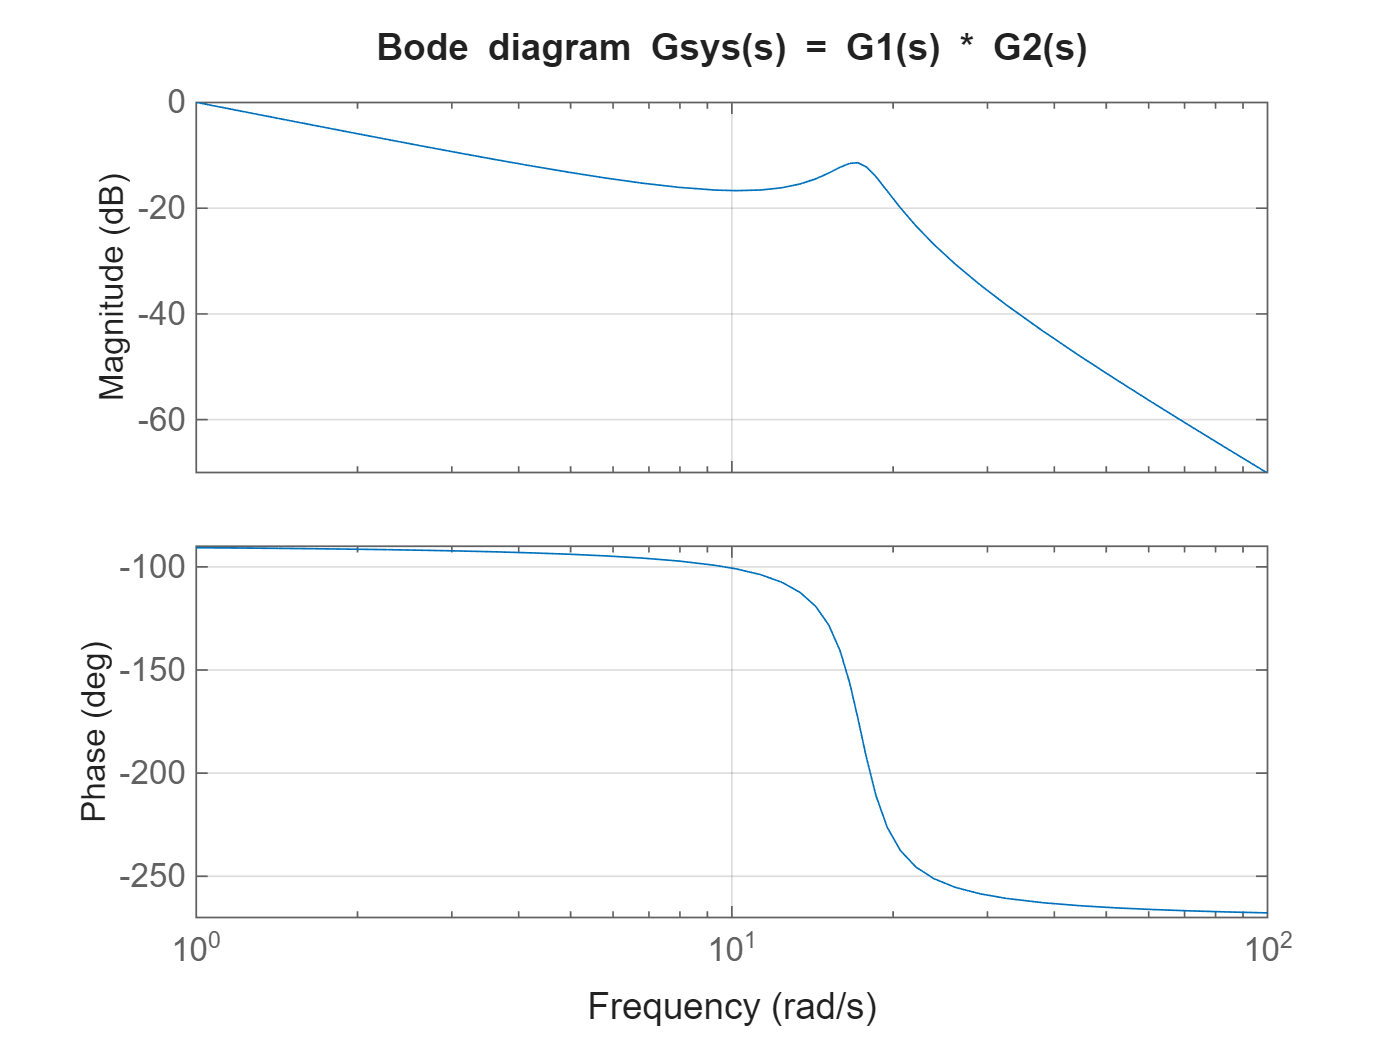

figure;
bode(G_sys);
title('Bode diagram G{sys}(s) = G{1}(s) * G{2}(s)');
grid on;

## P2)


$$\begin{array}{l}
G_2 \left(s\right)=\frac{1}{\;\frac{J}{c}s^2 +\frac{r}{c}s+1}=\frac{K}{T^2 s^2 +2\textrm{DTs}+1}\\
T=\sqrt{\frac{J}{c}}\\
D=\frac{\frac{r}{c}}{2T}\\
K=1
\end{array}$$


T = sqrt(J/c)

T = 0.0574

w_0 = 1/T

w_0 = 17.4078

D = (r/c) / (2 * T)  

D = 0.1088

Sytem behavior: as 0 < D < 1 it is a stable, oscillating system. It is lightly damped (D = 0.1088) with characteristic frequency 1/T = 17.4078 and system gain K = 1.

## P3)

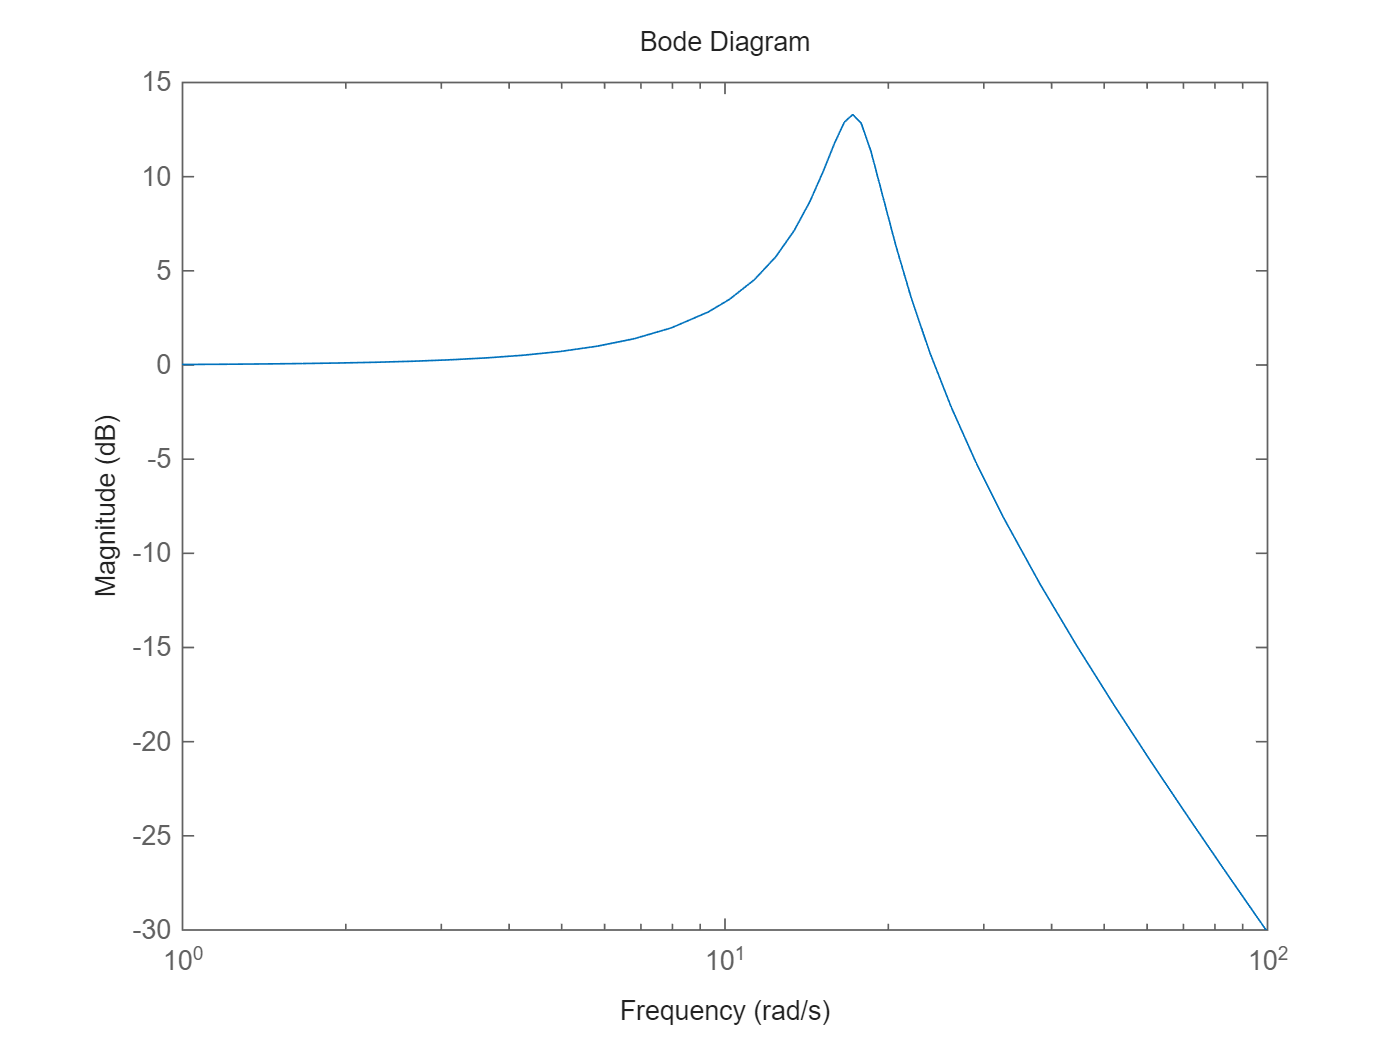

opts = bodeoptions;
opts.PhaseVisible = 'off'; 
bodeplot(G2, opts);

$K=\omega_{\to 0} =0\;\textrm{dB}=1$looking at the left in bode diagram

$T=\frac{1}{\omega_0 }$ and $\omega_0$ is at the peak of magnitude

D with value of peak magnitude: $|G\left(j\omega_0 \right)|\approx \frac{K}{2D}$


$$D=\frac{1}{2\cdot {10}^{\frac{13\ldotp 3}{20}} }=0\ldotp 108$$


## P4)

#### frequency response method of Ziegler and Nichols 

- controlling the system with a P-controller 

-  step input

-  increasing the controller gain K until the control loop executes a continuous oscillation

- 
$$K_{\textrm{krit}} =\textrm{controller}\;\textrm{gain}$$


- 
$$T_{\textrm{Krit}} =\textrm{period}\;\textrm{of}\;\textrm{oscillation}$$


- calculate controller parameters via table

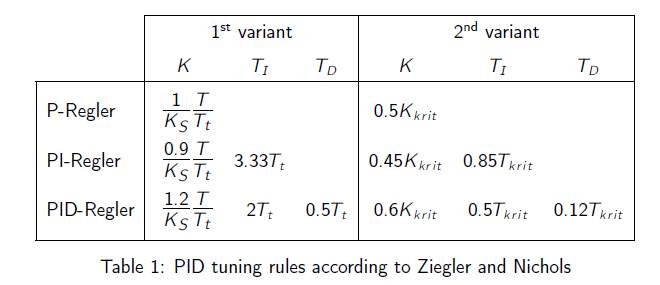

## P5) 

$G_y^* \left(s\right)=\frac{K}{\left(T_1 s+1\right)\left(T_2 s+1\right)\left(T_3 s+1\right)}$ with $G_y^* \left(0\right)=1\to K=1$ 


$$G_C \left(s\right)=\frac{1}{G\left(s\right)}\frac{G_y^* \left(s\right)}{1-G_y^* \left(s\right)}=\frac{\frac{1}{\left(T_1 s+1\right)\left(T_2 s+1\right)\left(T_3 s+1\right)}}{\left(\frac{1}{\frac{J}{c}s^3 +\frac{r}{c}s^2 +s}\right)\left(1-\left(\frac{1}{\left(T_1 s+1\right)\left(T_2 s+1\right)\left(T_3 s+1\right)}\right)\right)}$$


T1 = 0.7; T2 = 0.5; T3 = 0.8;
G_y_star = 1 / ((T1*s+1)*(T2*s+1)*(T3*s+1));
G_c = minreal(G_y_star/(G_sys*(1-G_y_star)))


G_c =
 
  0.01179 s^2 + 0.04464 s + 3.571
  -------------------------------
       s^2 + 4.679 s + 7.143
 
Continuous-time transfer function.
Model Properties


## P6)

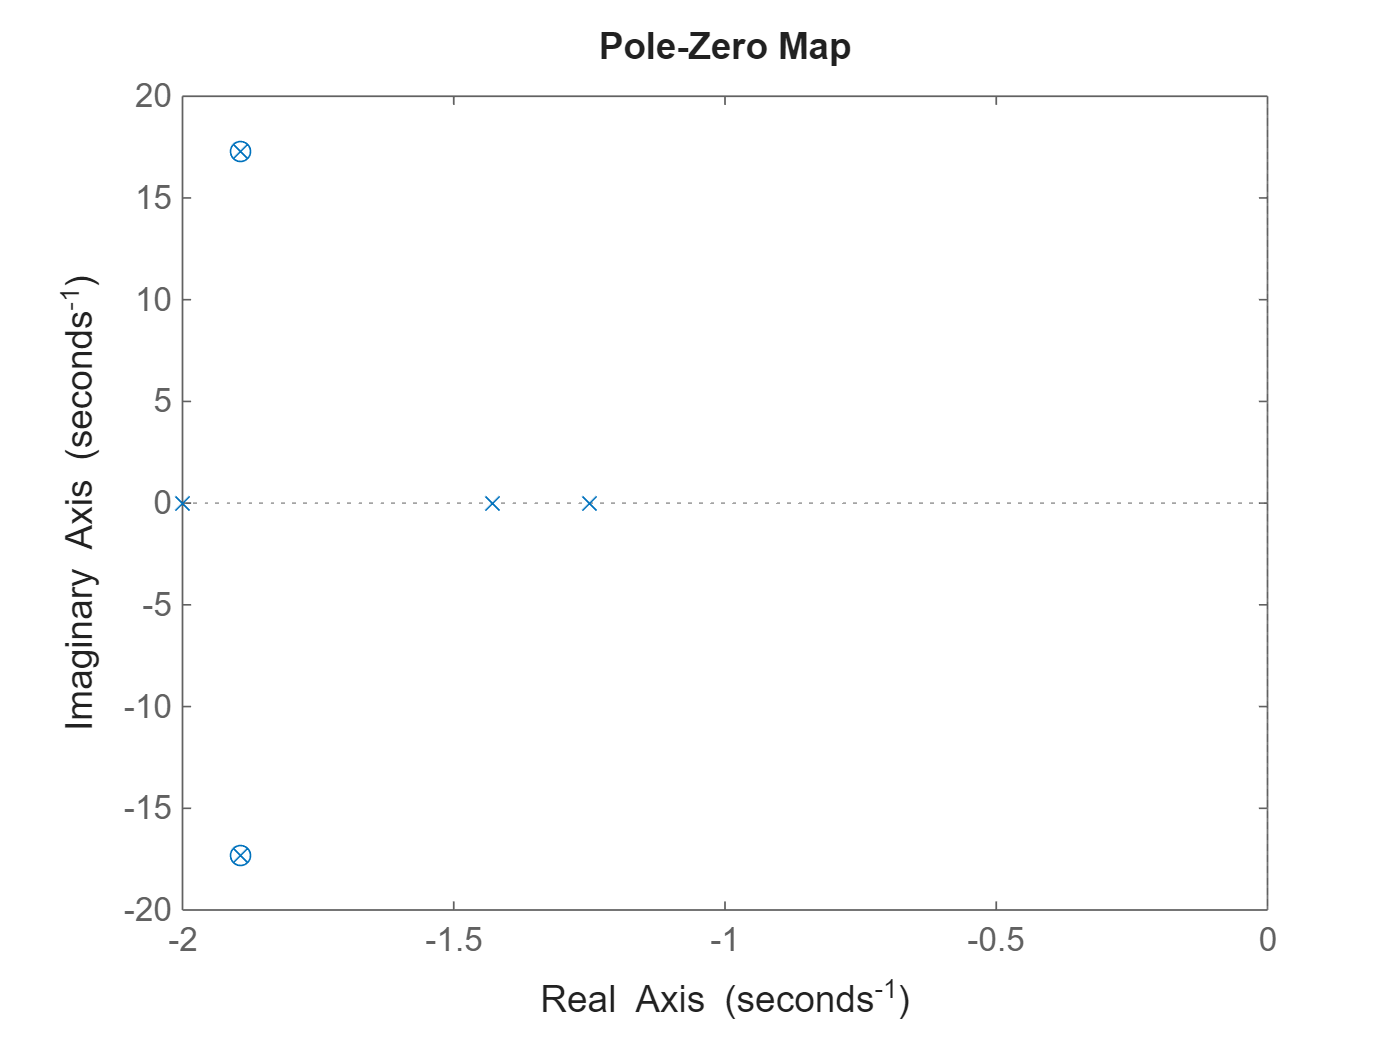

pzmap(feedback(G_c*G_sys,1))

All poles in the left half-plane. So the system is stable.

## P7)

Trajectory values at start and end must be the desired values.


$$y^* \left(0\right)=w_A ;y^* \left(T\right)=w_B$$


All derivatives of position (velocity, acceleration, jerk,  snap) at start and end value must be zero for smooth tracking without control spikes or overshoot. 


$$y^{*\left(i\right)} \left(t\right)|_{t=0} =0;y^{*\left(i\right)} \left(t\right)|_{t=T} =0$$


To ensure continuity of control varibale at start and end: $u^* \left(0\right)=\frac{a_0 }{b_0 }w_A ;\;u^* \left(T\right)=\frac{a_0 }{b_0 }w_B$

## P8)

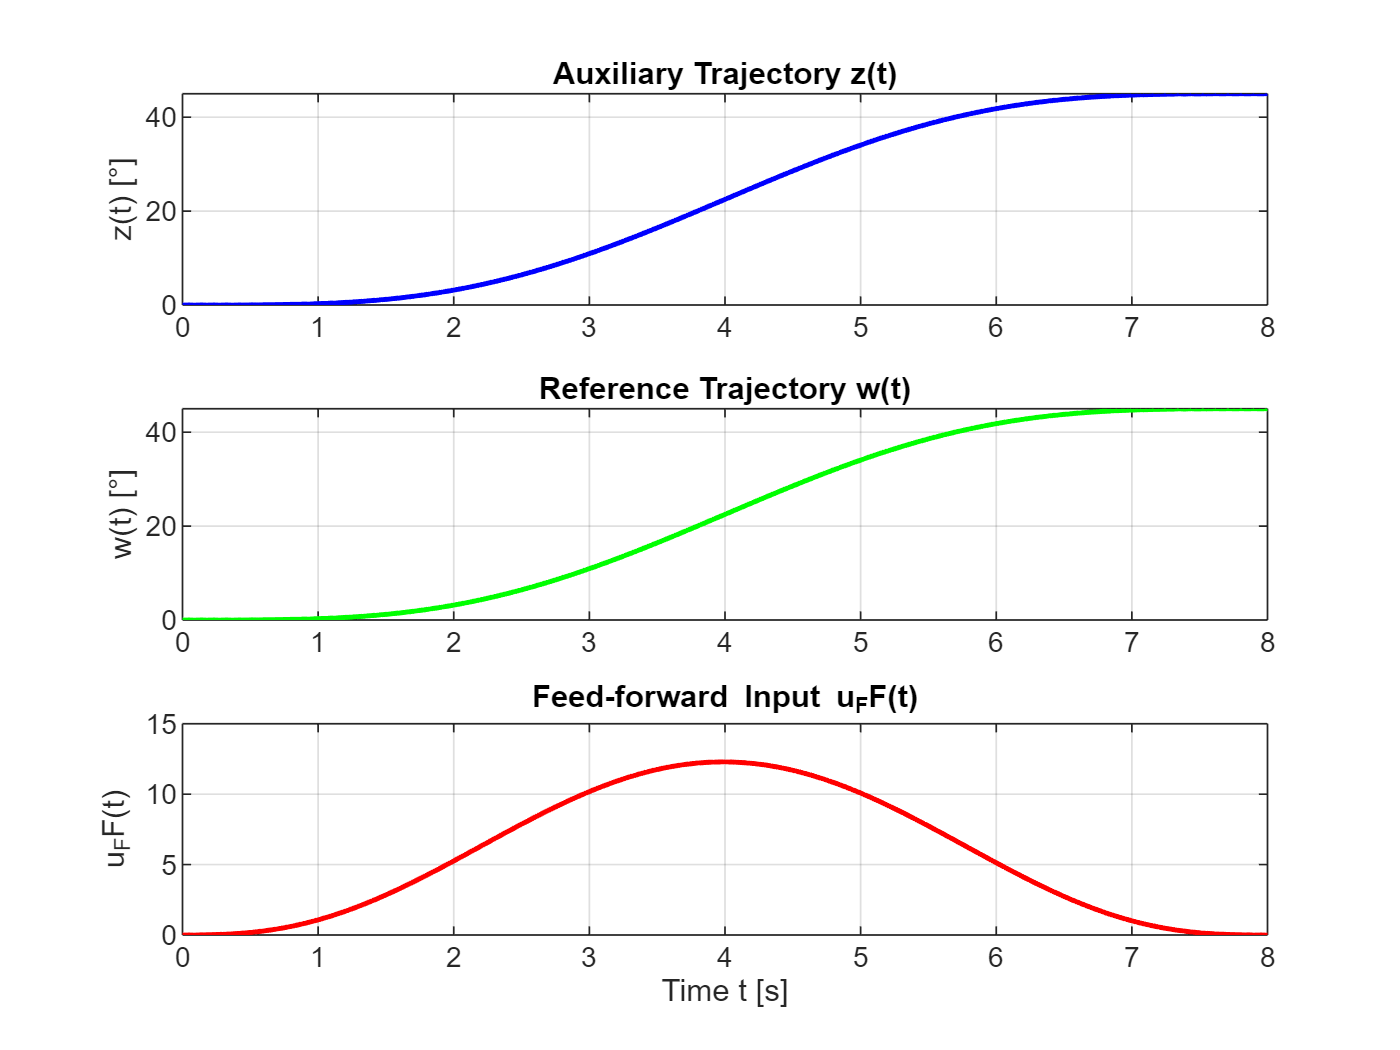

[num, den] = tfdata(G_sys, 'v');  
a = den;
b = num;

% auxillary trajectory
zA = 0;                   
zB = 45;
T  = 8;
t  = linspace(0, T, 1000);
tau = t / T;

% polynomial coefficients (n=3 -> line 3 from Tab. 1)
p4 = 35;  p5 = -84;  p6 = 70;  p7 = -20;

% Auxiliary trajectory z(t)
z = zA + (zB - zA) * (p4*tau.^4 + p5*tau.^5 + p6*tau.^6 + p7*tau.^7);

% derivatives
dt      = t(2) - t(1);
z_dot   = gradient(z, dt);
z_ddot  = gradient(z_dot, dt);
z_dddot = gradient(z_ddot, dt);


% Feedforward function
uFF = a(1)*z_dddot + a(2)*z_ddot + a(3)*z_dot + a(4)*z;

% reference trajectory
w  = b(4)*z;  


figure;
subplot(3,1,1)
plot(t, z,   'b','LineWidth',1.5); grid on
title('Auxiliary Trajectory z(t)')
ylabel('z(t) [°]')

subplot(3,1,2)
plot(t, w,   'g','LineWidth',1.5); grid on
title('Reference Trajectory w(t)')
ylabel('w(t) [°]')

subplot(3,1,3)
plot(t, uFF, 'r','LineWidth',1.5); grid on
title('Feed-forward Input u_FF(t)')
xlabel('Time t [s]')
ylabel('u_FF(t)')

## P9) 


$$\[
z(t) =
\begin{cases}
z_A & \text{for } t < t_b \\
z_A + (z_B - z_A) \cdot \sum_{i = n+1}^{2n+1} p_i \, (\frac{t - t_b}{T})^i & \text{for } t_b \leq t < t_b + T \\
z_B & \text{for } t \geq t_b + T
\end{cases}
\]
$$


- Stay constant at the initial value $z_A \;$before the change starts (i.e., for $t<t_b$)

- Smoothly transition from $z_A$� to $z_B$� over the interval $\left\lbrack t_b ,t_b +T\right\rbrack$,

- Stay constant at the final value $z_B$� after the transition ends (i.e., for $t\ge t_b +T$)

**Example:**

a trajectory from  $0\degree$ to $45\degree$, starting at $t_b =2\;s$ with duration $T=1\ldotp 5\;s$


$$\[
z(t) =
\begin{cases}
0^\circ, & \text{for } t < 2 \\
45^\circ \cdot \sum_{i = n+1}^{2n+1} p_i \, (\frac{t - 2}{1.5})^i& \text{for } 2 \leq t < 3.5 \\
45^\circ, & \text{for } t \geq 3.5
\end{cases}
\]
$$


## P10)

Calculate $\textrm{maximum}\;\textrm{of}\;u_{\textrm{FF}} \left(t\right)$. If the value is greater than $u_{\max }$we extend the duration $T$ of the trajectory and calculate again, until the maximum fits.

## P11)

### One DOF:


$$\begin{array}{l}
G_{y_w } \left(s\right)=\frac{G_C \left(s\right)\cdot G_{\textrm{sys}} \left(s\right)}{1+G_C \left(s\right)\cdot G_{\textrm{sys}} \left(s\right)}=\frac{G_C \left(s\right)\cdot G_1 \left(s\right)\cdot G_2 \left(s\right)}{1+G_C \left(s\right)\cdot G_1 \left(s\right)\cdot G_2 \left(s\right)}\\
G_{y_d } \left(s\right)=\frac{G_{\textrm{dis}} \left(s\right)}{1+G_C \left(s\right)\cdot G_{\textrm{dis}} \left(s\right)}=\frac{G_3 \left(s\right)\cdot G_2 \left(s\right)}{1+G_C \left(s\right)\cdot G_1 \left(s\right)\cdot G_2 \left(s\right)}
\end{array}$$


### Two DOF:


$$\begin{array}{l}
G_{y_w } \left(s\right)=G_{\textrm{FF}} \left(s\right)\cdot \;\frac{G_{\textrm{sys}} \left(s\right)}{1+G_C \left(s\right)\cdot G_{\textrm{sys}} \left(s\right)}+\frac{G_C \left(s\right)\cdot G_{\textrm{sys}} \left(s\right)}{1+G_C \left(s\right)\cdot G_{\textrm{sys}} \left(s\right)}=\frac{\left(G_{\textrm{FF}} \left(s\right)+G_C \left(s\right)\right)\cdot G_1 \left(s\right)\cdot G_2 \left(s\right)}{1+G_C \left(s\right)\cdot G_1 \left(s\right)\cdot G_2 \left(s\right)}\\
G_{y_d } \left(s\right)=\frac{G_{\textrm{dis}} \left(s\right)}{1+G_C \left(s\right)\cdot G_{\textrm{dis}} \left(s\right)}=\frac{G_3 \left(s\right)\cdot G_2 \left(s\right)}{1+G_C \left(s\right)\cdot G_1 \left(s\right)\cdot G_2 \left(s\right)}
\end{array}$$


## P12)

The behaviour in disturbance is the same for both control types as the transfer functions are identical. 

In the one-DOF control type, there is one controller for reference tracking and disturbance rejection. Optimizing the controller for one desired behaviour will influence the other.

In the two-DOF control type, there is a separte controller for the reference tracking. Both controller can be optimized independently.

## P13)

Yes it is possible. The model matching controller can be designed to achieve a good disturbance behaviour. By combination with a feedforward controller we can achieve fast and accurate reference tracking and robustness against external disturbances.

Further optimazations could be disturbance observers to handle external disturbances by estimation or adaptive control to adjust parameters in case of model variations.